## Phase Lagging Error from Phase Advanced Head

Ben Cellini

clear ; close all ; clc

Fs = 100; % sampleing rate [Hz]
T = 5; % simulation time [s]
t = (0:(1/Fs):T)'; % time vector [s]
f = 1; % sine wave ferquency [Hz]

stim_amp = 1; % stimulus amplitude
head_amp = 0.5; % head amplitude
stim_phase = 0; % stimulus phase
head_phase = deg2rad(40); % head phase: not "phase difference"
stim = stim_amp*sin(2*pi*f*t + stim_phase); % stimulus
head = head_amp*sin(2*pi*f*t + head_phase); % head
error = stim - head;

error_amp = sqrt((stim_amp)^(2) + (-head_amp)^(2) + 2*stim_amp*-head_amp*cos(head_phase)) % error amplitude calculated analytically, note head amplitude is negative because we are subtracting

error_amp = 0.6957

error_phase = asind(-head_amp*sin(head_phase) / error_amp)  % error phase calculated analytically

error_phase = -27.5157

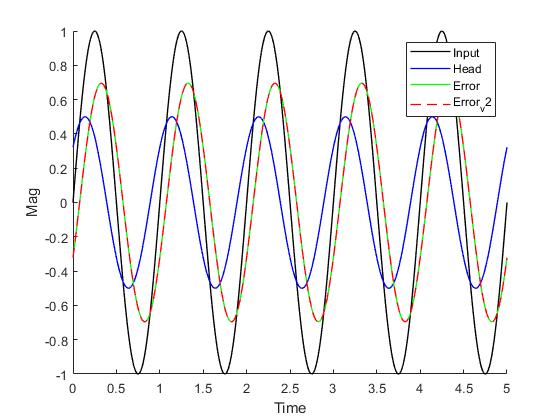

error_v2 = error_amp*sin(2*pi*f*t + deg2rad(error_phase)); % error calculated analytically

% Plot
figure (1) ; cla ; hold on
xlabel('Time')
ylabel('Mag')
plot(t, stim, 'k', 'LineWidth', 1)
plot(t, head, 'b', 'LineWidth', 1)
plot(t, error, 'g', 'LineWidth', 1)
plot(t, error_v2, '--r', 'LineWidth', 1)
legend('Input','Head','Error','Error_v2')